Description:

To run the Cobra toolbox you need first to download the repository as indicated [at this link](https://opencobra.github.io/cobratoolbox/stable/installation.html). Your cobra folder should be included within the file code.

clc;
clear all;
close all;

%Paremeters
fontsize=15;%for plotting

%including all parent folders up to the file 'code', this makes visible all
%files within this code, which includes the COBRA toolbox you need first to
%download as follows from the intr
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\bioelectrodynamics\code



initCobraToolbox(false) % false, as we don't want to update



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2026
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.49.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

%This lists all the versions of functions named initCobraToolbox in your matlab installation, after the current path, the version used is the first in this list.
which -all initCobraToolbox

D:\code\bioelectrodynamics\code\cobratoolbox~\initCobraToolbox.m


**Loading the model**

% Specify the MAT file you're looking for
% matFileName = 'model_aux.mat';
% matFileName = 'iMM904.mat';
matFileName = 'model_yeastGEM_v9_0_2.mat';
%place the current Matlab folder with the project files
cd(fileparts(which(matFileName)));
%load the model
model=readCbModel(matFileName);

Each model.subSystems{x} has been changed to a character array.


S = model.S;

We choose to operate with those metabolites that are observed in the largest concentration in the extracellular matrix of yeast cells. As described in [Fig. 1 C, 1] the first three metabolites are

- Glutamine: C5H10N2O3

- Glutamate: C5H7N2O4

- Alanine: C3H7NO2

We look at the metabolite candidates by their chemical formula within the [ChemSpider database](https://www.chemspider.com/).

met_Formulas = ["C4H4N2O2",... %Uracil
                  "C9H11NO2",... %Phenylalanine
                  "C6H13NO2",... %Leucine
                  "C11H12N2O2",... %Tryptophan
                  "C6H13NO2",... %L-Isoleucine
                  "C5H11NO2S",... %Methionine
                  "C2H7NO3S",... %Taurine
                  "C5H11NO2",... %L-Valine
                  "C5H9NO2",... %DL-Proline
                  "C9H11NO3",... %L-Tyrosine
                  "C3H7NO2",... %Alanine
                  "C4H9NO3",... %L-Threonine
                  "C2H5NO2",... %Glycine
                  "C5H10N2O3",... %Glutamine
                  "C5H8NO4", ... %L-Glutamate
                  "C3H7NO3", ... %L-Serine
                  "C4H8N2O3", ... %L-Asparagine
                  "C4H5NO4", ... %Aspartate    ===== NOT FOUND
                  "C6H9N3O2", ... %L-Histidine
                  "C6H15N4O2", ... %L-Arginine
                  "C6H14N2O2",... %Lysine    ===== NOT FOUND
                  "C6H13N3O3", ... %L-Citrulline
                  "C5H12N2O2", ... %Ornithine ===== NOT FOUND
                  ];  

met_Labels = [    "U",... %Uracil
                  "F",... %Phenylalanine
                  "L",... %Leucine
                  "W",... %Tryptophan
                  "I",... %L-Isoleucine
                  "M",... %Methionine
                  "Tau",... %Taurine
                  "V",... %L-Valine
                  "P",... %DL-Proline
                  "Y",... %L-Tyrosine
                  "A",... %Alanine
                  "T",... %L-Threonine
                  "G",... %Glycine
                  "Q",... %Glutamine
                  "E", ... %L-Glutamate
                  "S", ... %L-Serine
                  "N", ... %L-Asparagine
                  "D", ... %Aspartate    ===== NOT FOUND
                  "H", ... %L-Histidine
                  "R", ... %L-Arginine
                  "K",... %Lysine    ===== NOT FOUND
                  "Cit", ... %L-Citrulline
                  "O", ... %Ornithine ===== NOT FOUND
                  ]

met_Labels = 1×23 string array
    "U"    "F"    "L"    "W"    "I"    "M"    "Tau"    "V"    "P"    "Y"    "A"    "T"    "G"    "Q"    "E"    "S"    "N"    "D"    "H"    "R"    "K"    "Cit"    "O"



met_candidates = [];
met_candidate_labels = [];

i_label = 1;

for f = met_Formulas

    idx = find(strcmpi(strtrim(string(model.metFormulas)), strtrim(f)));

    fprintf('\nFormula %s: %d hits\n', f, numel(idx));
    disp(table(string(model.mets(idx)), ...
               string(model.metNames(idx)), ...
               string(model.metFormulas(idx)), ...
        'VariableNames', {'metId','metName','formula'}));

    if ~isempty(idx)

        baseLabel = met_Labels(i_label);

        % If only one hit → keep simple label
        if numel(idx) == 1
            newLabels = baseLabel;
        else
            % Multiple hits → append numbers
            newLabels = baseLabel + string(1:numel(idx))';
        end

        met_candidates = [met_candidates; idx(:)];
        met_candidate_labels = [met_candidate_labels; newLabels(:)];
    end

    i_label = i_label + 1;
end


Formula C4H4N2O2: 2 hits


     metId      metName      formula  
    ________    ________    __________

    "s_1550"    "uracil"    "C4H4N2O2"
    "s_1551"    "uracil"    "C4H4N2O2"




Formula C9H11NO2: 4 hits


     metId           metName          formula  
    ________    _________________    __________

    "s_1032"    "L-phenylalanine"    "C9H11NO2"
    "s_1033"    "L-phenylalanine"    "C9H11NO2"
    "s_1034"    "L-phenylalanine"    "C9H11NO2"
    "s_4296"    "D-phenylalanine"    "C9H11NO2"




Formula C6H13NO2: 8 hits


     metId         metName         formula  
    ________    ______________    __________

    "s_1016"    "L-isoleucine"    "C6H13NO2"
    "s_1017"    "L-isoleucine"    "C6H13NO2"
    "s_1018"    "L-isoleucine"    "C6H13NO2"
    "s_1019"    "L-isoleucine"    "C6H13NO2"
    "s_1021"    "L-leucine"       "C6H13NO2"
    "s_1022"    "L-leucine"       "C6H13NO2"
    "s_1023"    "L-leucine"       "C6H13NO2"
    "s_1024"    "L-leucine"       "C6H13NO2"




Formula C11H12N2O2: 3 hits


     metId         metName          formula   
    ________    ______________    ____________

    "s_1048"    "L-tryptophan"    "C11H12N2O2"
    "s_1049"    "L-tryptophan"    "C11H12N2O2"
    "s_1050"    "L-tryptophan"    "C11H12N2O2"




Formula C6H13NO2: 8 hits


     metId         metName         formula  
    ________    ______________    __________

    "s_1016"    "L-isoleucine"    "C6H13NO2"
    "s_1017"    "L-isoleucine"    "C6H13NO2"
    "s_1018"    "L-isoleucine"    "C6H13NO2"
    "s_1019"    "L-isoleucine"    "C6H13NO2"
    "s_1021"    "L-leucine"       "C6H13NO2"
    "s_1022"    "L-leucine"       "C6H13NO2"
    "s_1023"    "L-leucine"       "C6H13NO2"
    "s_1024"    "L-leucine"       "C6H13NO2"




Formula C5H11NO2S: 4 hits


     metId         metName          formula  
    ________    ______________    ___________

    "s_1029"    "L-methionine"    "C5H11NO2S"
    "s_1030"    "L-methionine"    "C5H11NO2S"
    "s_1031"    "L-methionine"    "C5H11NO2S"
    "s_3758"    "L-methionine"    "C5H11NO2S"




Formula C2H7NO3S: 2 hits


     metId       metName      formula  
    ________    _________    __________

    "s_1471"    "taurine"    "C2H7NO3S"
    "s_1472"    "taurine"    "C2H7NO3S"




Formula C5H11NO2: 3 hits


     metId       metName       formula  
    ________    __________    __________

    "s_1056"    "L-valine"    "C5H11NO2"
    "s_1057"    "L-valine"    "C5H11NO2"
    "s_1058"    "L-valine"    "C5H11NO2"




Formula C5H9NO2: 3 hits


     metId        metName       formula 
    ________    ___________    _________

    "s_1035"    "L-proline"    "C5H9NO2"
    "s_1036"    "L-proline"    "C5H9NO2"
    "s_1037"    "L-proline"    "C5H9NO2"




Formula C9H11NO3: 6 hits


     metId        metName        formula  
    ________    ____________    __________

    "s_1051"    "L-tyrosine"    "C9H11NO3"
    "s_1052"    "L-tyrosine"    "C9H11NO3"
    "s_1053"    "L-tyrosine"    "C9H11NO3"
    "s_1054"    "L-tyrosine"    "C9H11NO3"
    "s_1055"    "L-tyrosine"    "C9H11NO3"
    "s_3858"    "D-tyrosine"    "C9H11NO3"




Formula C3H7NO2: 5 hits


     metId         metName         formula 
    ________    ______________    _________

    "s_0441"    "beta-alanine"    "C3H7NO2"
    "s_0955"    "L-alanine"       "C3H7NO2"
    "s_0956"    "L-alanine"       "C3H7NO2"
    "s_0957"    "L-alanine"       "C3H7NO2"
    "s_3759"    "L-alanine"       "C3H7NO2"




Formula C4H9NO3: 7 hits


     metId           metName          formula 
    ________    _________________    _________

    "s_0958"    "L-allothreonine"    "C4H9NO3"
    "s_1014"    "L-homoserine"       "C4H9NO3"
    "s_1015"    "L-homoserine"       "C4H9NO3"
    "s_1045"    "L-threonine"        "C4H9NO3"
    "s_1046"    "L-threonine"        "C4H9NO3"
    "s_1047"    "L-threonine"        "C4H9NO3"
    "s_4043"    "L-threonine"        "C4H9NO3"




Formula C2H5NO2: 5 hits


     metId          metName          formula 
    ________    ________________    _________

    "s_1003"    "L-glycine"         "C2H5NO2"
    "s_1004"    "L-glycine"         "C2H5NO2"
    "s_1005"    "L-glycine"         "C2H5NO2"
    "s_3839"    "L-glycine"         "C2H5NO2"
    "s_3934"    "Ethylnitronate"    "C2H5NO2"




Formula C5H10N2O3: 8 hits


     metId         metName         formula  
    ________    _____________    ___________

    "s_0999"    "L-glutamine"    "C5H10N2O3"
    "s_1000"    "L-glutamine"    "C5H10N2O3"
    "s_1001"    "L-glutamine"    "C5H10N2O3"
    "s_1002"    "L-glutamine"    "C5H10N2O3"
    "s_3755"    "L-glutamine"    "C5H10N2O3"
    "s_3838"    "Ala-Gly"        "C5H10N2O3"
    "s_4170"    "Ala-Gly"        "C5H10N2O3"
    "s_4171"    "Ala-Gly"        "C5H10N2O3"




Formula C5H8NO4: 6 hits


     metId         metName        formula 
    ________    _____________    _________

    "s_0991"    "L-glutamate"    "C5H8NO4"
    "s_0992"    "L-glutamate"    "C5H8NO4"
    "s_0993"    "L-glutamate"    "C5H8NO4"
    "s_0994"    "L-glutamate"    "C5H8NO4"
    "s_0995"    "L-glutamate"    "C5H8NO4"
    "s_0996"    "L-glutamate"    "C5H8NO4"




Formula C3H7NO3: 6 hits


     metId       metName       formula 
    ________    __________    _________

    "s_1039"    "L-serine"    "C3H7NO3"
    "s_1040"    "L-serine"    "C3H7NO3"
    "s_1041"    "L-serine"    "C3H7NO3"
    "s_1042"    "L-serine"    "C3H7NO3"
    "s_3107"    "L-serine"    "C3H7NO3"
    "s_3904"    "D-Serine"    "C3H7NO3"




Formula C4H8N2O3: 4 hits


     metId         metName         formula  
    ________    ______________    __________

    "s_0969"    "L-asparagine"    "C4H8N2O3"
    "s_0970"    "L-asparagine"    "C4H8N2O3"
    "s_0971"    "L-asparagine"    "C4H8N2O3"
    "s_0972"    "L-asparagine"    "C4H8N2O3"




Formula C4H5NO4: 0 hits


    metId    metName    formula
    _____    _______    _______





Formula C6H9N3O2: 4 hits


     metId         metName        formula  
    ________    _____________    __________

    "s_1006"    "L-histidine"    "C6H9N3O2"
    "s_1007"    "L-histidine"    "C6H9N3O2"
    "s_1008"    "L-histidine"    "C6H9N3O2"
    "s_1009"    "L-histidine"    "C6H9N3O2"




Formula C6H15N4O2: 4 hits


     metId        metName         formula  
    ________    ____________    ___________

    "s_0965"    "L-arginine"    "C6H15N4O2"
    "s_0966"    "L-arginine"    "C6H15N4O2"
    "s_0967"    "L-arginine"    "C6H15N4O2"
    "s_0968"    "L-arginine"    "C6H15N4O2"




Formula C6H14N2O2: 0 hits


    metId    metName    formula
    _____    _______    _______





Formula C6H13N3O3: 2 hits


     metId         metName          formula  
    ________    ______________    ___________

    "s_0979"    "L-citrulline"    "C6H13N3O3"
    "s_4166"    "L-citrulline"    "C6H13N3O3"




Formula C5H12N2O2: 0 hits


    metId    metName    formula
    _____    _______    _______




#### Metabolic network

Description: This block finds the metabolic network between the selected metabolites

S = model.S;
met_candidates = met_candidates(:);
numMets = numel(met_candidates);

glob2loc = containers.Map('KeyType','int32','ValueType','int32');
for k = 1:numMets
    glob2loc(int32(met_candidates(k))) = int32(k);
end

% Use cell array to store reaction names per edge
edgeRxns = cell(numMets);

for r = 1:size(S,2)

    col = S(:,r);

    reactGlob = find(col < 0);
    prodGlob  = find(col > 0);

    reactGlob = reactGlob(ismember(reactGlob, met_candidates));
    prodGlob  = prodGlob(ismember(prodGlob,  met_candidates));

    if isempty(reactGlob) || isempty(prodGlob)
        continue
    end

    for a = 1:numel(reactGlob)
        i = double(glob2loc(int32(reactGlob(a))));
        for b = 1:numel(prodGlob)
            j = double(glob2loc(int32(prodGlob(b))));

            % Append reaction name to this edge
            edgeRxns{i,j} = [edgeRxns{i,j}, {model.rxns{r}}];
        end
    end
end

s = [];
t = [];
edgeLabels = {};

for i = 1:numMets
    for j = 1:numMets
        if ~isempty(edgeRxns{i,j})
            s(end+1) = i;
            t(end+1) = j;

            % Combine multiple reaction names into one string
            edgeLabels{end+1} = strjoin(edgeRxns{i,j}, ', ');
        end
    end
end

Gdir = digraph(s, t);   % no edge weights
%store the metabolites
Gdir.Nodes.Name = met_candidate_labels;
%store the reaction names
Gdir.Edges.Reaction = edgeLabels';

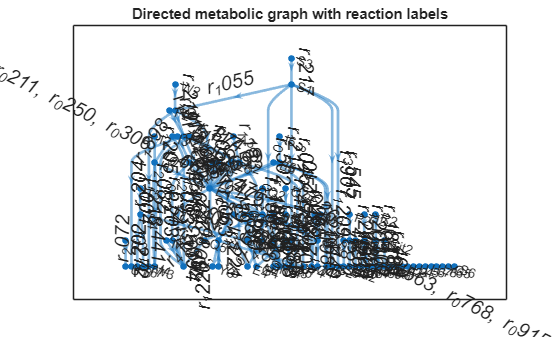


figure;
p = plot(Gdir, 'Layout','layered','LineWidth',2,'EdgeFontSize',fontsize);

p.NodeLabel = Gdir.Nodes.Name;
p.EdgeLabel = Gdir.Edges.Reaction;

title('Directed metabolic graph with reaction labels');

## Step 1: 

Description: Looking for such nodes that receives multiples metabolites. This step selects the metabolite like $m_4$, that is produced by two different chemical reactions like $r_2$ and $r_3$ in Fig. 1. This is accomplished within the step above by the red dots. In this case select the chemical reactions and metabolites as exbited in Fig. 1

branchNodes = [];
A = adjacency(Gdir);   % directed adjacency matrix

for j = 1:Gdir.numnodes

    incoming = find(A(:,j));
    incoming(incoming == j) = [];

    targetBase = getBaseLabel(Gdir.Nodes.Name{j});

    validSources = [];

    for i = incoming'
        sourceBase = getBaseLabel(Gdir.Nodes.Name{i});

        if ~strcmp(sourceBase, targetBase)
            validSources(end+1) = i;
        end
    end

    if numel(unique(validSources)) >= 2
        branchNodes(end+1) = j;
    end
end

disp("Nodes with >=2 distinct incoming branches (excluding same-family):");

Nodes with >=2 distinct incoming branches (excluding same-family):


disp(Gdir.Nodes.Name(branchNodes));

    {'Y1'}
    {'G1'}
    {'E1'}
    {'E3'}



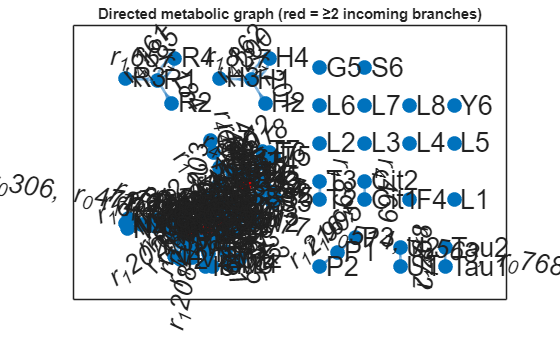


numNodes = numnodes(Gdir);

% Default color = blue
nodeColors = repmat([0 0.447 0.741], numNodes, 1);   % MATLAB default blue

% Highlight convergence nodes in red
nodeColors(branchNodes, :) = repmat([1 0 0], numel(branchNodes), 1);

figure;

p = plot(Gdir, 'Layout','force','LineWidth',2,'EdgeFontSize',fontsize);   % 'layered' also works

p.NodeLabel = Gdir.Nodes.Name;
p.NodeColor = nodeColors;

p.EdgeLabel = Gdir.Edges.Reaction;

p.MarkerSize = 10;
p.LineWidth = 2;
p.EdgeFontSize = fontsize+5;
p.NodeFontSize = fontsize+5;

title('Directed metabolic graph (red = ≥2 incoming branches)');

#### Mapping a 2 neurons network into the metabolic reaction

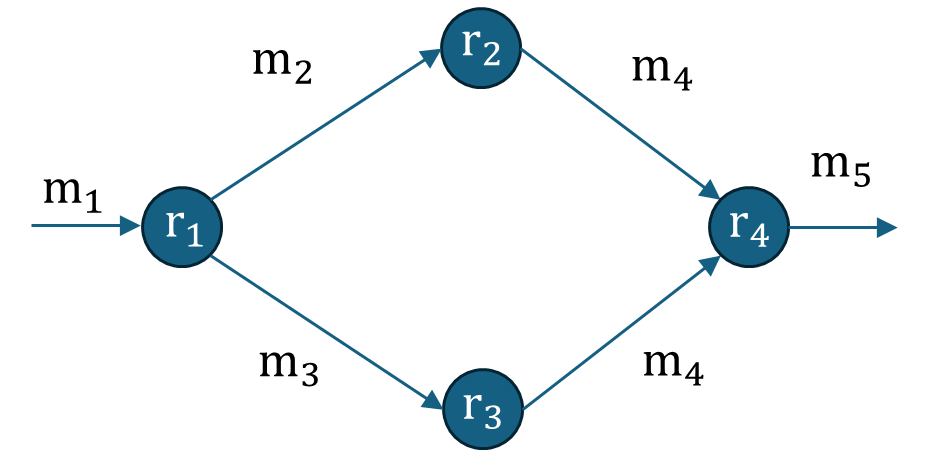

Fig. 1: 2-neurons NN.

#### **Step 2** 

**Descritpion:** Look on the metabolites identified above as As represented in  Fig. 3, we look for the chemical reaction $r_1$ that produces the metabolites $\text{m}_2$ and $\text{m}_3$.

m2_label = "E1";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_E1=find(model.S(m2,:)>0);

m2_label = "T1";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_T1=find(model.S(m2,:)>0);

m2_label = "T4";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_T4=find(model.S(m2,:)>0);

m2_label = "A2";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_A2=find(model.S(m2,:)>0);

m2_label = "S1";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_S1=find(model.S(m2,:)>0);

m2_label = "F1";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_F1=find(model.S(m2,:)>0);

m2_label = "W1";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_W1=find(model.S(m2,:)>0);

m2_label = "I5";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_I5=find(model.S(m2,:)>0);

m2_label = "V1";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_V1=find(model.S(m2,:)>0);

m2_label = "I1";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_I1=find(model.S(m2,:)>0);

m2_label = "Q3";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_Q3=find(model.S(m2,:)>0);

m2_label = "A4";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_A4=find(model.S(m2,:)>0);

m2_label = "V3";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_V3=find(model.S(m2,:)>0);

m2_label = "I3";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_I3=find(model.S(m2,:)>0);

m2_label = "I7";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_I7=find(model.S(m2,:)>0);

m2_label = "I7";
idx = find(ismember(met_candidate_labels, m2_label));
m2 = met_candidates(idx);
producers_Q5=find(model.S(m2,:)>0);

%Node Y1
any(ismember(producers_A2,producers_E1))

ans = logical
   0



%Node G1
any(ismember(producers_T1,producers_S1))

ans = logical
   0


any(ismember(producers_T1,producers_A2))

ans = logical
   0


any(ismember(producers_S1,producers_A2))

ans = logical
   0




%Node E1
any(ismember(producers_A2,producers_F1))

ans = logical
   0


any(ismember(producers_A2,producers_W1))

ans = logical
   0


any(ismember(producers_A2,producers_I5))

ans = logical
   0


any(ismember(producers_A2,producers_V1))

ans = logical
   0


any(ismember(producers_A2,producers_I1))

ans = logical
   0


any(ismember(producers_A2,producers_Q3))

ans = logical
   0



any(ismember(producers_F1,producers_W1))

ans = logical
   0


any(ismember(producers_F1,producers_I5))

ans = logical
   0


any(ismember(producers_F1,producers_V1))

ans = logical
   0


any(ismember(producers_F1,producers_I1))

ans = logical
   0


any(ismember(producers_F1,producers_Q3))

ans = logical
   0



any(ismember(producers_W1,producers_I5))

ans = logical
   0


any(ismember(producers_W1,producers_V1))

ans = logical
   0


any(ismember(producers_W1,producers_I1))

ans = logical
   0


any(ismember(producers_W1,producers_Q3))

ans = logical
   0



any(ismember(producers_I5,producers_V1))

ans = logical
   0


any(ismember(producers_I5,producers_I1))

ans = logical
   0


any(ismember(producers_I5,producers_Q3))

ans = logical
   0



any(ismember(producers_I1,producers_Q3))

ans = logical
   0



%Node E3
any(ismember(producers_A4,producers_V3))

ans = logical
   0


any(ismember(producers_A4,producers_I3))

ans = logical
   0


any(ismember(producers_A4,producers_I7))

ans = logical
   0


any(ismember(producers_A4,producers_Q5))

ans = logical
   0



any(ismember(producers_I3,producers_I7))

ans = logical
   0


any(ismember(producers_I3,producers_Q5))

ans = logical
   0



any(ismember(producers_I7,producers_Q5))

ans = logical
   0


#### Mapping a 2 neurons network into the metabolic reaction

Fig. 1: 2-neurons NN.

**Algorithm:**

- **Step 1**: Look first for metabolites like $m_4$, that is produced by two different chemical reactions like $r_2$ and $r_3$ in Fig. 1. This is accomplished by looking on each row of the stochiometry matrix S the case where 2 coefficients are larger than zero, and one is less than zero. As illustrated in Fig. 2, such a row means that there are two chemical reactions $r_i$ and $r_j$ producing the metabolite of index $m$, as well as chemical reaction $r_k$ consuming it. That is, the chemical reactions $r_i$ and $r_j$ map to $r_2$ and $r_3$ in Fig. 1, while $r_k$ maps to $r_4$.

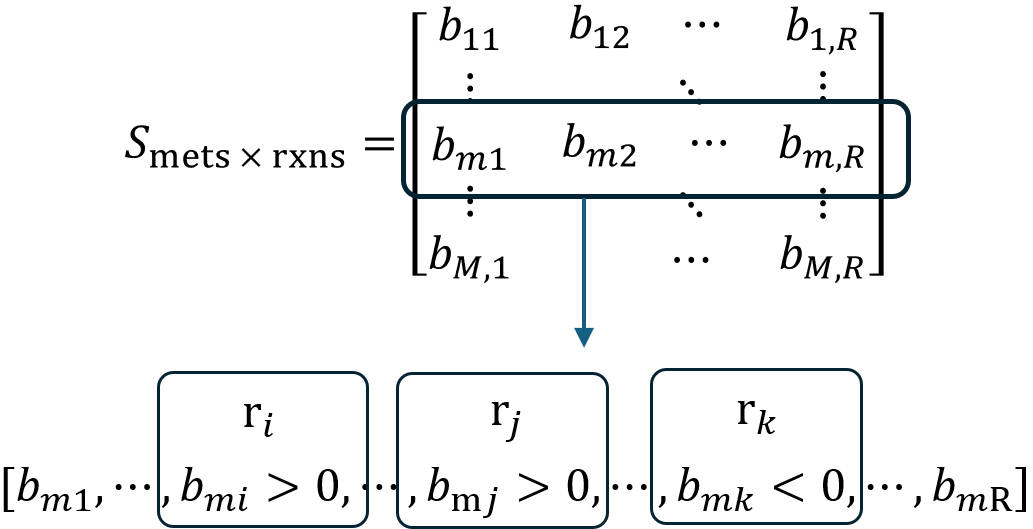

Fig. 2: Description of Step 1.

- **Step 2:** As represented in  Fig. 3, we look for the metabolites $\text{m}_2$ and $\text{m}_3$ that are produced by the same chemical reaction $r_1$ and are consumed by the  chemical reactions $r_2$ and $r_3$. In general, this step finds within the two chemical reactions from the above step (within the corresponding columns in the matrix S), two rows that produces the metabolites like  $m_2$ and $m_3$ with the same chemical reaction, like $r_1$ (Fig. 1), and those metabolites are also consumed by the chemical reactions $r_2$ and $r_3$. This step is divided into two sub-steps

- Step 2.1: Find the rows of the matrix S, where $r_2$ and $r_3$ consumes a metabolite

- Step 2.2: In those rows from Step 2.1, find those chemical reactions that produces that metabolite in the row.

- Step 2.3: Find the common index in those rows in Step 2.2 where they are both positive. This index identifies the chemical reaction $r_1$ like.

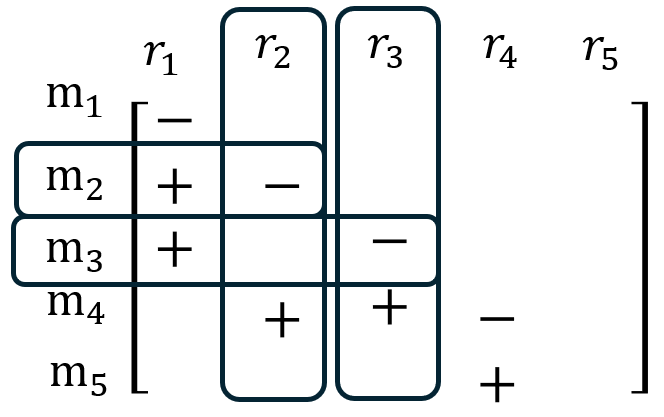

Fig. 3: Description of the Step 2.

#### Step 3


S = model.S;

% %testing matrix
% S=[-1  0  0  0  0,
%     1 -1  0  0  0,
%     1  0 -1  0  0,
%     0  1  1 -1  0,
%     0  0  0  0  0]
% 
% %testing matrix
% S=[ 1 -1  0  0  0,
%     1 -1  0  0  0,
%     1  0 -1  0  0,
%     0  1  1 -1  0,
%     0  0  0  0  0]
% 
% %testing matrix
% S=[ 1 -1  0  0  0,
%     1 -1  0  0  0,
%     1  0 -1  0  0,
%     0  1  1 -1  0,
%     1 -1 -1  0  0]

%% Optional: filter out "currency metabolites"
badMetPatterns = ["h[", "h2o[", "atp[", "adp[", "pi[", "ppi[", ...
                  "nad[", "nadh[", "nadp[", "nadph["];

isBadMet = false(numel(model.mets),1);
for k = 1:numel(badMetPatterns)
    isBadMet = isBadMet | contains(lower(string(model.mets)), badMetPatterns(k));
end

%% Helper functions for GPR interpretation

% A reaction is considered single-gene if its GPR rule:
% - is non-empty
% - contains no logical AND / OR operators
isSingleGeneRule = @(rule) ...
    strlength(rule) > 0 && ...
    ~contains(lower(rule), ' and ') && ...
    ~contains(lower(rule), ' or ');

% Extract gene identifiers appearing in a GPR rule (best-effort tokenization)
parseGeneList = @(rule) unique( ...
    regexp(rule, '[A-Za-z0-9_:\-\.]+', 'match') );

% Logical vector indicating whether each reaction is controlled by one gene
isSingleGene = false(numel(model.rxns),1);

%% Storage for motif results
results_Step_1 = [];
idx_motif = 1;
total_idx_motif=10E10;

% Scan per reaction a pattern, where a metabolite is consumed and at least
% N others are produced, but those producing the same metabolite

%% Scan each metabolite row in S for a 2-producer / 1-consumer junction

[met_total, reaction_total]=size(S);

%identifying those metabolites to avoid
m_H2O=find(contains(model.metNames,'H2O'));
m_H=find(contains(model.metNames,'H'));
m_ATP=find(contains(model.metNames,'ATP'));

m4_label = "E1";
idx = find(ismember(met_candidate_labels, m4_label));
m4 = met_candidates(idx);
producers_E1=find(model.S(m2,:)>0);


for k = 1:length(met_candidates)

    m=met_candidates(k);

    % if isBadMet(m)
    %     continue;
    % end

    %avoid a metabolite as water
    if(ismember(m,m_H2O) || ismember(m,m_H) || ismember(m,m_ATP))
        continue;
    end


    row = S(m,:);

    %find those reactions that produced the metabolite m
    producers = find(row > 0);
    %find those reactions that consumes the metabolite m
    consumers = find(row < 0);

    % % Keep only producers that are single-gene-controlled
    % producersSG = producers(isSingleGene(producers));

    % if numel(producersSG) < 2 || numel(consumers) < 1
    %     continue;
    % end

    %avoid those metabolites that are not produced by two separate chemical
    %reactions and consumed by a third one
    if numel(producers) < 2 || numel(consumers) < 1
        continue;
    end

    %storing those chemical reaction rates in results_Step_1
    %Evaluating the pairs of chemical reactions within the same metabolite
    r_pairs=nchoosek(producers,2);
    [r_total,~]=size(r_pairs);

    for i_r=1:r_total
        %% --- Gene information  ---
        %Only saving those reactions where a gene mediates
        % Raw GPR rule for reaction 2
        gpr2 = string(model.grRules{r_pairs(i_r,1)});
        % Extract all genes appearing in the GPR of reaction 2
        genes2 = strings(0,1);
        if strlength(gpr2) > 0
            genes2 = string(parseGeneList(gpr2))';
            genes2 = genes2(~ismember(lower(genes2), ["and","or"]));
        else
            continue;
        end

        % Raw GPR rule for reaction 3
        gpr3 = string(model.grRules{r_pairs(i_r,2)});
        % Extract all genes appearing in the GPR of reaction 1
        genes3 = strings(0,1);
        if strlength(gpr3) > 0
            genes3 = string(parseGeneList(gpr3))';
            genes3 = genes3(~ismember(lower(genes3), ["and","or"]));
        else
            continue;
        end

        %looking for those chemical reactions where different genes
        %mediates
        if(isequal(genes2,genes3))
            continue;
        end

        results_Step_1(idx_motif).m4=m;        
        results_Step_1(idx_motif).r2=r_pairs(i_r,1);
        results_Step_1(idx_motif).r3=r_pairs(i_r,2);    

        idx_motif=idx_motif+1;

        if (idx_motif==total_idx_motif)
            break;
        end

    end

    if (idx_motif==total_idx_motif)
        break;
    end
end

idx_Motif_1=1;
%% Convert results to a table for inspection
if isempty(results_Step_1)
    Motifs_Step_1 = table();
else
    Motifs_Step_1 = struct2table(results_Step_1);
end

Motifs_Step_1

Motifs_Step_1 = 622×3 table
     m4     r2      r3 
    ____    ___    ____

    1195    282     998
    1195    282    3410
    1195    998    3410
     823    947    1507
     807    934     936
     807    934     937
     807    936     937
     812    940     942
     812    940     943
     812    942     943
     815    941    3568
     839    811     951
     807    934     936
     807    934     937
     807    936     937
     812    940     942



fprintf('Metabolite m4: %s',string(model.metFormulas(Motifs_Step_1.m4(idx_Motif_1))));

Metabolite m4: C4H4N2O2


fprintf('Reaction 2: %s',string(model.rxnNames(Motifs_Step_1.r2(idx_Motif_1))));

Reaction 2: cytosine deaminase

rxnFstr  = reactionToString_chm(model, Motifs_Step_1.r2(idx_Motif_1), true);
fprintf('  %s\n', rxnFstr);

  C4H5N3O + H + H2O  ->  H4N + C4H4N2O2



fprintf('Reaction 3: %s',string(model.rxnNames(Motifs_Step_1.r3(idx_Motif_1))));

Reaction 3: uracil transport

rxnFstr  = reactionToString_chm(model, Motifs_Step_1.r3(idx_Motif_1), true);
fprintf('  %s\n', rxnFstr);

  H + C4H4N2O2  ->  H + C4H4N2O2


#### Step 4

%% Storage for motif results
results_Step_2 = [];
%Each column of represent a combination per item, for instance the first
%column tells the metabolites and chemical reactions that follows the
%structure in Fig.1, the second column another combination of metabolites
%and chemical reactions for the same structure, and so on.

idx_motif = 1;

R2=[results_Step_1.r2];
R3=[results_Step_1.r3];

%pick up the first metabolite in the repeating series of unique metabolites
% [values, first_indices] = unique(A, 'stable')
[~, idx_mets] = unique([results_Step_1.m4], 'stable');
% limit number of structures
limit_arch_met=1;%number of architectures per metabolite m4 %consider to stop on those architectures that are placed in the same place
count_arch_met=1;

number_arch=2;%number of architectures that has been found in total

%looping in the number of reactions r2 that produces metabolite m4
for i_r2_uniq=1:length(idx_mets)
    i_r2 = idx_mets(i_r2_uniq);

    %stop with the number or architectures are met
    if(idx_motif>number_arch)
        break;
    end

    %Step 2.1: Find the rows of the matrix S, where r_2 consumes a metabolite
    met_consumer_r2 = find(S(:,R2(i_r2))<0);

    %looping in the number of reactions r3 that produces metabolite m4
    % for i_r3=1:length(R3)
    %     %Avoiding the same chemical reactions r2 and r3
    %     if(i_r3==i_r2)
    %         continue;
    %     end

        %Step 2.1: Find the rows of the matrix S, where r_3 consumes a metabolite
        met_consumer_r3=find(S(:,results_Step_1(i_r2).r3)<0);
        
        %looping on those consumed metabolites by reaction r2
        for i_m_r2=1:length(met_consumer_r2)
            %looping on those consumed metabolites by reaction r3
            for i_m_r3=1:length(met_consumer_r3)
                
                %Avoiding the same metabolites m2 and m3
                if(i_m_r3==i_m_r2)
                    continue;
                end


                %Step 2.2: In those rows from Step 2.1, find those chemical reactions that produces that metabolite in the row.
                idx_met_r2=met_consumer_r2(i_m_r2);
                idx_met_r3=met_consumer_r3(i_m_r3);
                reaction_producer_r2=find(S(idx_met_r2,:)>0);
                reaction_producer_r3=find(S(idx_met_r3,:)>0);
        
                %Avoiding metabolites of water and hydrogen
                if(ismember(idx_met_r2,m_H2O) || ismember(idx_met_r2,m_H) || ismember(idx_met_r2,m_ATP) || ...
                   ismember(idx_met_r3,m_H2O) || ismember(idx_met_r3,m_H) || ismember(idx_met_r3,m_ATP))
                    continue;
                end
                %Avoiding the same consumed metabolite
                if(idx_met_r2==idx_met_r3)
                    continue;
                end

                %Step 2.3: Find the common index in the two rows in Step 2.2 where both metabolites are positive.
                % This index identifies the chemical reaction  like.
                reaction_producer_r1=intersect(reaction_producer_r2,reaction_producer_r3);
        
                if(isempty(reaction_producer_r1))
                    continue;
                end
                 %avoiding reactions r2 and r3 with the same gene
                 r2=results_Step_1(i_r2).r2;
                 r3=results_Step_1(i_r2).r3;
                 gpr2=model.grRules{r2};
                 gpr3=model.grRules{r3};
                 if(ismember(gpr2,gpr3))
                     continue;
                 end

                if(~isempty(reaction_producer_r1))
                    for i=1:length(reaction_producer_r1)
                        % Removing those reactions of zero genes
                        % Raw GPR rule for reaction 3
                        gpr1 = string(model.grRules{reaction_producer_r1(i)});
                        % Extract all genes appearing in the GPR of reaction 1
                        genes1 = strings(0,1);
                        if strlength(gpr1) > 0
                            genes1 = string(parseGeneList(gpr1))';
                            genes1 = genes1(~ismember(lower(genes1), ["and","or"]));
                        else
                            continue;
                        end
                       
                        %avoiding reaction r1 with same genes as r2 or r3
                        if(ismember(gpr1,gpr2) || ismember(gpr1,gpr3))
                            continue;
                        end

                        %saving the results
                        %Related to the output metabolite fo reaction 1 and 2
                        results_Step_2(idx_motif).m4=results_Step_1(i_r2).m4;
                        

                        %Info related to reaction 2
                        results_Step_2(idx_motif).r2=results_Step_1(i_r2).r2;                        
                        results_Step_2(idx_motif).m2=met_consumer_r2(i_m_r2);
                        

                        %Info related to reaction 3
                        results_Step_2(idx_motif).r3=results_Step_1(i_r2).r3;
                        results_Step_2(idx_motif).m3=met_consumer_r3(i_m_r3);
                       

                        %Info related to reaction 1
                        results_Step_2(idx_motif).r1=reaction_producer_r1(i);
                        

                        idx_motif=idx_motif+1;
                        
                        if(count_arch_met>limit_arch_met)
                            break;
                        end

                        count_arch_met=count_arch_met+1;
                    end                    
                end
                if(count_arch_met>limit_arch_met)
                    break;
                end
            end
            if(count_arch_met>limit_arch_met)
                break;
            end
        end
        if(count_arch_met>limit_arch_met)
            count_arch_met=1;
        end
    % end
    % if(count_arch_met>limit_arch_met)
    %     count_arch_met=1;       
    % end
end


idx_Motif_2=1;
%% Convert results to a table for inspection
if isempty(results_Step_1)
    Motifs_Step_2 = table();
else
    Motifs_Step_2 = struct2table(results_Step_2);
end

Error using struct2table (line 13)
Input structure must be a scalar structure, or a structure array with one column or one row.


fprintf('\n=============================\n');
fprintf(' Motif_Step_2 row: %d\n', idx_Motif_2);
fprintf('=============================\n');

m2=(Motifs_Step_2.m2(idx_Motif_2));
m3=(Motifs_Step_2.m3(idx_Motif_2));
m4=(Motifs_Step_2.m4(idx_Motif_2));

fprintf('Metabolite m2: Formula: %s | Name: %s| %s   | ID: %s ', string(model.metFormulas(m2)),...
                                                                   string(model.metNames(m2)), ...
                                                                   string(m2), ...
                                                                   string(model.mets(m2)));

fprintf('Metabolite m3: Formula: %s | Name: %s| %s   | ID: %s ', string(model.metFormulas(m3)),...
                                                                   string(model.metNames(m3)), ...
                                                                   string(m3), ...
                                                                   string(model.mets(m3)));

fprintf('Metabolite m4: Formula: %s | Name: %s| %s   | ID: %s ', string(model.metFormulas(m4)),...
                                                                   string(model.metNames(m4)), ...
                                                                   string(m4), ...
                                                                   string(model.mets(m4)));

% reactionToString_chm(model, Motifs_Step_2.r2(idx), false);

r1=Motifs_Step_2.r1(idx_Motif_2);
fprintf('Reaction 1: %s',string(model.rxnNames(r1)));
rxnFstr  = reactionToString_chm(model, r1, true);
fprintf('  %s\n', rxnFstr);
fprintf('  Genes:  %s\n', string(model.grRules(r1)));
getReactionLocationString(model,r1)
fprintf(' Location: %s\n', getReactionLocationString(model,r1));
fprintf(' EC code: %s\n', string(model.eccodes(r1)));

r2=Motifs_Step_2.r2(idx_Motif_2);
fprintf('Reaction 2: %s',string(model.rxnNames(r2)));
rxnFstr  = reactionToString_chm(model, r2, true);
fprintf('  %s\n', rxnFstr);
fprintf('  Genes:  %s\n', string(model.grRules(r2)));
fprintf(' Location: %s\n', getReactionLocationString(model,r2));
fprintf(' EC code: %s\n', string(model.eccodes(r2)));

r3=Motifs_Step_2.r3(idx_Motif_2);
fprintf('Reaction 3: %s',string(model.rxnNames(r3)));
rxnFstr  = reactionToString_chm(model, r3, true);
fprintf('  %s\n', rxnFstr);
fprintf('  Genes:  %s\n', string(model.grRules(r3)));
fprintf(' Location: %s\n', getReactionLocationString(model,r3));
fprintf(' EC code: %s\n', string(model.eccodes(r3)));

## ---------------- Helper functions ----------------

function printMotifLine_Step2(model, Motifs_Step_2, idx)
% printMotifLine_Step2
%
% Prints a selected line (row) from Motifs_Step_2 with:
%   - adder metabolite (m4) name + formula
%   - the key "output"/junction metabolites (m2, m3) if present
%   - reactions r1, r2, r3 as:
%       1) metabolite-ID equation
%       2) chemical-formula equation
%       3) GPR rule (as stored in Motifs_Step_2.gpr*)
%       4) EC code (from model.eccodes, if present)
%       5) Location + Subsystem (if present in model)
%
% Requirements:
%   - You already have the helper functions you posted earlier:
%       reactionToString_chm, getReactionLocationString, getReactionSubsystemString
%   - Motifs_Step_2 is built from results_Step_2 via struct2table.

fprintf('\n=============================\n');
fprintf(' Motif_Step_2 row: %d\n', idx);
fprintf('=============================\n');

% ---------- Adder metabolite m4 ----------
m4idx  = getMetIndexFlexible(Motifs_Step_2, idx, "m4");
m4name = string(model.metNames(m4idx)); %safeGetString(Motifs_Step_2, idx, "m4_name");
m4id   = metIDfromIndex(model, m4idx);
m4f    = metFormulaFromIndex(model, m4idx);

fprintf('Metabolite m4: %s', m4id);
if strlength(m4name) > 0, fprintf('  | name: %s', m4name); end
if strlength(m4f)    > 0, fprintf('  | formula: %s', m4f); end
fprintf('\n');

% ---------- Optional: junction/output metabolites m2, m3 ----------
printMetLineIfExists(model, Motifs_Step_2, idx, "m2", "m2_string", "Metabolite m2");
printMetLineIfExists(model, Motifs_Step_2, idx, "m3", "m3_string", "Metabolite m3");
fprintf('\n');

% ---------- Reactions r1, r2, r3 ----------
printOneRxnBlock(model, Motifs_Step_2, idx, "r1", "r1_string", "gpr1", "r1");
printOneRxnBlock(model, Motifs_Step_2, idx, "r2", "r2_string", "gpr2", "r2");
printOneRxnBlock(model, Motifs_Step_2, idx, "r3", "r3_string", "gpr3", "r3");



fprintf('\n');
end

%% ---------------- Helper functions (NEW) ----------------

function printOneRxnBlock(model, T, idx, rxnField, rxnNameField, gprField, label)
% Prints a single reaction block from the table row.

rxnIdx = getRxnIndexFlexible(model, T, idx, rxnField, rxnNameField);

fprintf('%s: ', label);

% Try to print a reaction identifier (model.rxns entry if index is known)
if ~isempty(rxnIdx)
    fprintf('%s', string(model.rxns{rxnIdx}));
else
    % fall back to stored string if present
    rxnIDmaybe = safeGetString(T, idx, rxnField);
    if strlength(rxnIDmaybe) == 0
        rxnIDmaybe = safeGetString(T, idx, rxnNameField);
    end
    if strlength(rxnIDmaybe) == 0
        fprintf('(unknown reaction)');
    else
        fprintf('%s', rxnIDmaybe);
    end
end

% Optional: human name
rxnName = safeGetString(T, idx, rxnNameField);
if strlength(rxnName) > 0 && ~(rxnName == "(missing)")
    fprintf('  | name: %s', rxnName);
end
fprintf('\n');

if isempty(rxnIdx)
    fprintf('  (reaction not found in model)\n\n');
    return;
end

% 1) Chemical reaction with metabolite IDs
rxnIDstr = reactionToString_chm(model, rxnIdx, false);
fprintf('  %s\n', rxnIDstr);

% 2) Chemical reaction with formulas
rxnFstr  = reactionToString_chm(model, rxnIdx, true);
fprintf('  %s\n', rxnFstr);

% 3) GPR rule (print EXACT rule, as requested)
gpr = safeGetString(T, idx, gprField);
if strlength(gpr) == 0 || gpr == "(missing)"
    % fall back to model.grRules if you didn't store it in the table row
    if isfield(model,'grRules') && numel(model.grRules) >= rxnIdx && ~isempty(model.grRules{rxnIdx})
        gpr = string(model.grRules{rxnIdx});
    else
        gpr = "";
    end
end

if strlength(gpr) > 0
    fprintf('  GPR: %s\n', gpr);
else
    fprintf('  GPR: none annotated\n');
end

% 4) EC codes (if available)
if isfield(model,'eccodes') && numel(model.eccodes) >= rxnIdx && ~isempty(model.eccodes{rxnIdx})
    fprintf('  EC: %s\n', string(model.eccodes{rxnIdx}));
else
    fprintf('  EC: none annotated\n');
end

% 5) Location + Subsystem (if your earlier helpers are in path)
try
    fprintf('  Location: %s\n', getReactionLocationString(model, rxnIdx));
catch
    % ignore if helper not present
end

try
    fprintf('  Subsystem: %s\n', getReactionSubsystemString(model, rxnIdx));
catch
    % ignore if helper not present
end

fprintf('\n');
end

function rxnIdx = getRxnIndexFlexible(model, T, idx, rxnField, rxnNameField)
% Tries hard to convert what's stored in T.(rxnField) / T.(rxnNameField)
% into a reaction index in model.rxns.
%
% Works if T stores:
%   - numeric reaction indices
%   - reaction IDs that exist in model.rxns
%   - reaction names that exist in model.rxnNames (fallback)

rxnIdx = [];

% 1) If rxnField is numeric, treat as direct index
if ismember(rxnField, T.Properties.VariableNames)
    val = T.(rxnField)(idx,:);
    if isnumeric(val) && isscalar(val) && ~isnan(val) && val >= 1 && val <= numel(model.rxns)
        rxnIdx = double(val);
        return;
    end
end

% 2) Try rxnField as a reaction ID string in model.rxns
rxnID = safeGetString(T, idx, rxnField);
if strlength(rxnID) > 0 && rxnID ~= "(missing)"
    hit = find(strcmp(model.rxns, rxnID), 1);
    if ~isempty(hit)
        rxnIdx = hit;
        return;
    end
end

% 3) Try rxnNameField as reaction ID (sometimes people store IDs there)
rxnID2 = safeGetString(T, idx, rxnNameField);
if strlength(rxnID2) > 0 && rxnID2 ~= "(missing)"
    hit = find(strcmp(model.rxns, rxnID2), 1);
    if ~isempty(hit)
        rxnIdx = hit;
        return;
    end
end

% 4) Try rxnNameField as reaction name in model.rxnNames (if available)
if isfield(model,'rxnNames') && ismember(rxnNameField, T.Properties.VariableNames)
    rxnName = safeGetString(T, idx, rxnNameField);
    if strlength(rxnName) > 0 && rxnName ~= "(missing)"
        hit = find(strcmp(string(model.rxnNames), rxnName), 1);
        if ~isempty(hit)
            rxnIdx = hit;
            return;
        end
    end
end
end

function mIdx = getMetIndexFlexible(T, idx, metField)
% Reads a metabolite index from T.(metField) if present.
mIdx = [];
if ismember(metField, T.Properties.VariableNames)
    v = T.(metField)(idx,:);
    if isnumeric(v) && isscalar(v) && ~isnan(v)
        mIdx = double(v);
    end
end
end

function printMetLineIfExists(model, T, idx, metField, metStrField, label)
% Prints a metabolite line if the table contains the requested fields.
mIdx = getMetIndexFlexible(T, idx, metField);

metID = "";
metF  = "";
if ~isempty(mIdx) && mIdx >= 1 && mIdx <= numel(model.mets)
    metID = string(model.mets{mIdx});
    metName = string(model.metNames{mIdx});
    metF  = metFormulaFromIndex(model, mIdx);
else
    % fall back to stored string if provided
    metID = safeGetString(T, idx, metStrField);
end

if strlength(metID) == 0 || metID == "(missing)"
    return;
end

fprintf('%s: %s | %s', label, metID, metName);
if strlength(metF) > 0
    fprintf('  | formula: %s', metF);
end
fprintf('\n');
end

function s = safeGetString(T, idx, fieldName)
% Safely fetches T.(fieldName)(idx) as string; returns "(missing)" if absent.
s = "(missing)";
if ~ismember(fieldName, T.Properties.VariableNames)
    return;
end
try
    v = T.(fieldName)(idx,:);
    if iscell(v)
        v = v{1};
    end
    s = string(v);
    if ismissing(s), s = ""; end
catch
    s = "(missing)";
end
end

function metID = metIDfromIndex(model, mIdx)
% Returns metabolite ID from index, else empty.
metID = "";
if ~isempty(mIdx) && mIdx >= 1 && mIdx <= numel(model.mets)
    metID = string(model.mets{mIdx});
end
end

function metF = metFormulaFromIndex(model, mIdx)
% Returns formula from index if available, else empty.
metF = "";
if ~isempty(mIdx) && isfield(model,'metFormulas') && numel(model.metFormulas) >= mIdx ...
        && ~isempty(model.metFormulas{mIdx})
    metF = string(model.metFormulas{mIdx});
end
end

% function printMotifReactionsWithFormulas(model, Motifs, idx)
% % printMotifReactionsWithFormulas
% %
% % Prints reactions associated with one Motifs row in the following order:
% %   1) reaction with metabolite IDs
% %   2) reaction with chemical formulas
% %   3) associated gene(s)
% %   4) associated enzyme EC code(s)
% 
% fprintf('\n=== Motif %d ===\n', idx);
% fprintf('Adder metabolite: %s (%s)\n\n', Motifs.m4(idx),string(model.metFormulas(Motifs.m4(idx))));
% 
% rxnNames  = {Motifs.r2_Name(idx), Motifs.r3_Name(idx)};
% rxnLabels = {'r2 (input)', 'r3  (input)'};
% 
% for k = 1:numel(rxnNames)
% 
%     rxnID = rxnNames{k};
%     r = find(strcmp(model.rxns, rxnID));
% 
%     if isempty(r)
%         fprintf('%s: reaction not found\n\n', rxnLabels{k});
%         continue;
%     end
% 
%     fprintf('%s: %s\n', rxnLabels{k}, rxnID);
% 
%     % 1) Reaction using metabolite IDs
%     rxnIDstr = reactionToString_chm(model, r, false);
%     fprintf('%s\n', rxnIDstr);
% 
%     % 2) Reaction using chemical formulas
%     rxnFstr = reactionToString_chm(model, r, true);
%     fprintf('%s\n', rxnFstr);
% 
%     % 3) Gene information
%     geneStr = getReactionGeneString(model, r);
%     if strlength(geneStr) == 0
%         fprintf('gene(s): none annotated\n');
%     else
%         fprintf('%s\n', geneStr);
%     end
% 
%     % 4) Enzyme EC code(s)
%     if isfield(model,'eccodes') && numel(model.eccodes) >= r ...
%             && ~isempty(model.eccodes{r})
%         fprintf('EC: %s\n', model.eccodes{r});
%     else
%         fprintf('EC: none annotated\n');
%     end
% 
%     fprintf('\n');
% end
% end

function rxnStr = reactionToString_chm(model, r, useFormula)
% Converts reaction r into a readable chemical equation.
% useFormula = false → metabolite IDs; true → chemical formulas (if available).

col = model.S(:,r);
metIdx = find(col ~= 0);

reactants = {};
products  = {};

for i = 1:numel(metIdx)
    m = metIdx(i);
    coeff = full(col(m));

    if useFormula
        metName = getMetFormula(model, m);
    else
        metName = string(model.mets{m});
    end

    if coeff < 0
        reactants{end+1} = formatTerm(-coeff, metName); %#ok<AGROW>
    elseif coeff > 0
        products{end+1}  = formatTerm(coeff, metName);  %#ok<AGROW>
    end
end

lhs = strjoinOrEmpty(reactants);
rhs = strjoinOrEmpty(products);

rxnStr = sprintf('%s  ->  %s', lhs, rhs);
end

function f = getMetFormula(model, m)
% Returns chemical formula for metabolite m if available, else metabolite ID.
if isfield(model,'metFormulas') && numel(model.metFormulas) >= m && ~isempty(model.metFormulas{m})
    f = string(model.metFormulas{m});
else
    f = string(model.mets{m});
end
end

function term = formatTerm(coeff, name)
% Formats a term like "ATP[c]" or "2 ATP[c]"
if abs(coeff - 1) < 1e-9
    term = string(name);
else
    term = sprintf('%g %s', coeff, string(name));
end
end

function s = strjoinOrEmpty(list)
% Joins terms with " + " or returns the empty symbol if list is empty.
if isempty(list)
    s = '∅';
else
    s = strjoin(string(list), ' + ');
end
end

function geneStr = getReactionGeneString(model, r)
% Returns "gene: X" or "gene(s): A;B;C" or "" if none annotated.

genes = strings(0,1);

% Preferred: rxnGeneMat
if isfield(model,'rxnGeneMat') && ~isempty(model.rxnGeneMat) && isfield(model,'genes')
    gIdx = find(model.rxnGeneMat(r,:));
    if ~isempty(gIdx)
        genes = string(model.genes(gIdx));
    end
end

% Fallback: parse grRules
if isempty(genes) && isfield(model,'grRules') && numel(model.grRules) >= r
    rule = string(model.grRules{r});
    if strlength(rule) > 0
        toks = regexp(rule, '[A-Za-z0-9_:\-\.]+', 'match');
        toks = unique(string(toks));
        toks = toks(~ismember(lower(toks), ["and","or"]));
        genes = toks;
    end
end

if isempty(genes)
    geneStr = "";
    return;
end

if numel(genes) == 1
    geneStr = sprintf('gene: %s', genes(1));
else
    geneStr = sprintf('gene(s): %s', strjoin(genes, ';'));
end
end

function locStr = getReactionLocationString(model, r)
% Infers compartments involved in reaction r from participating metabolites,
% then maps to human-readable names using model.compNames (if available).
%
% Returns a semicolon-separated string of compartment names (or IDs).

metIdx = find(model.S(:,r) ~= 0);

% Try the most reliable way first: model.metComps (index into model.comps)
compIDs = strings(0,1);

if isfield(model,'metComps') && ~isempty(model.metComps) && isfield(model,'comps')
    cIdx = unique(model.metComps(metIdx));
    compIDs = string(model.comps(cIdx));
else
    % Fallback: parse compartment tags like "glc6p[c]" → "c"
    mets = string(model.mets(metIdx));
    tags = regexp(mets, '\[([^\]]+)\]', 'tokens', 'once');
    tags = tags(~cellfun(@isempty, tags));
    if ~isempty(tags)
        compIDs = unique(string([tags{:}]));
    end
end

if isempty(compIDs)
    locStr = "unknown";
    return;
end

% Map compartment IDs to compartment names if available
if isfield(model,'compNames') && isfield(model,'comps') && ~isempty(model.compNames)
    comps = string(model.comps);
    compNames = string(model.compNames);

    names = strings(size(compIDs));
    for i = 1:numel(compIDs)
        j = find(comps == compIDs(i), 1);
        if ~isempty(j) && j <= numel(compNames) && strlength(compNames(j)) > 0
            names(i) = compNames(j);
        else
            names(i) = compIDs(i); % fallback
        end
    end
    locStr = strjoin(unique(names), '; ');
else
    locStr = strjoin(unique(compIDs), '; ');
end
end

function subStr = getReactionSubsystemString(model, r)
% Returns the subsystem annotation for reaction r.
% Handles common storage types: cell array, string array, or missing.

subStr = "unknown";

if isfield(model,'subSystems') && ~isempty(model.subSystems)
    ss = model.subSystems;

    if iscell(ss)
        if numel(ss) >= r && ~isempty(ss{r})
            subStr = string(ss{r});
        end
    else
        % string array / categorical / char array variants
        try
            if numel(ss) >= r
                subStr = string(ss(r));
            end
        catch
            % leave as unknown
        end
    end
end
end

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function base = getBaseLabel(label)
    base = regexprep(label,'\d+$','');   % remove trailing digits
end

#### References

[1] Kate Campbell, Jakob Vowinckel, Michael Mülleder, Silke Malmsheimer, Nicola Lawrence, Enrica Calvani, Leonor Miller-Fleming, Mohammad T Alam, Stefan Christen, Markus A Keller, Markus Ralser (2015) Self-establishing communities enable cooperative metabolite exchange in a eukaryote eLife 4:e09943  [https://doi.org/10.7554/eLife.09943](https://elifesciences.org/articles/09943)